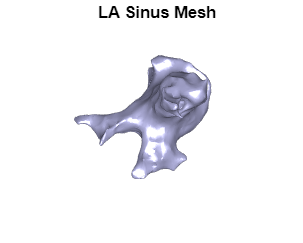

clc; clearvars; close all;

% 1) Load data
matData = load('Matfile/2-LA_SINUS.mat');
V       = matData.vertices;         % N x 3 vertex coordinates
F_raw   = matData.faces;            % raw face data
UBcell  = matData.UniqueBiEGMs;     % 1 x 58 cell, each cell is a matrix (time x channel)
Locs    = matData.UniqueElectrodePosition;  % 1 x 58 cell, each contains 22x3 double (3D positions)

% Reshape faces if needed
if isrow(F_raw)
    F = reshape(F_raw, 3, []).';
else
    F = F_raw;
end

% 2) Visualize mesh
figure;
trisurf(triangulation(F, V), 'FaceColor', [0.8 0.8 1], 'EdgeColor', 'none');
axis equal off; camlight headlight; lighting gouraud;
title('LA Sinus Mesh');

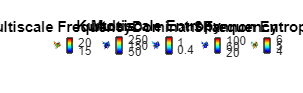


% 3) Compute features: MSF, Kurtosis, SampEn (channels 1-15)
nLocs = numel(UBcell);
RA2MSF = cell(1, nLocs);
RA2KT  = cell(1, nLocs);
RA2MSE = cell(1, nLocs);

for i = 1:nLocs
    sigAll = UBcell{i};  % matrix of size T x 22
    RA2MSF{i} = nan(1,15);
    RA2KT{i}  = nan(1,15);
    RA2MSE{i} = nan(1,15);
    RA2DF{i}= nan(1,15);
    RA2SE{i}= nan(1,15);
    for j = 1:15
        s = sigAll(:, j);
        RA2MSF{i}(j) = MSF_1D(s', 1000, dominant_freq(s, 1000));
        RA2KT{i}(j)  = kurtosis(s);
        RA2MSE{i}(j) = SampEn(s, 5);
        RA2DF{i}(j) = dominant_freq(s,1000);
        RA2SE{i}(j) = Shn_ent(s);

    end
end

% 4) Flatten to assign values to coordinates
allPts = zeros(nLocs * 15, 3);
allMSF = zeros(nLocs * 15, 1);
allKT  = zeros(nLocs * 15, 1);
allMSE = zeros(nLocs * 15, 1);
allDF = zeros(nLocs * 15, 1);
allSE = zeros(nLocs * 15, 1);
idx = 0;
for i = 1:nLocs
    allPts(idx+1:idx+15, :) = Locs{i}(1:15, :);
    allMSF(idx+1:idx+15)    = RA2MSF{i}(:);
    allKT(idx+1:idx+15)     = RA2KT{i}(:);
    allMSE(idx+1:idx+15)    = RA2MSE{i}(:);
    allDF(idx+1:idx+15)    = RA2DF{i}(:);
    allSE(idx+1:idx+15)    = RA2SE{i}(:);
    idx = idx + 15;
end

% 5) Smooth feature maps using KNN
K = 6;
[idxNN, ~] = knnsearch(allPts, V, 'K', K);
smMSF  = mean(allMSF(idxNN), 2);
smKT   = mean(allKT(idxNN), 2);
smMSE  = mean(allMSE(idxNN), 2);
smDF  = mean(allDF(idxNN), 2);
smSE  = mean(allSE(idxNN), 2);

% 6) Plot feature maps
figure('Position', [100 100 1400 400]);

subplot(1, 5, 1);
patch('Vertices', V, 'Faces', F, 'FaceVertexCData', smMSF, 'FaceColor', 'interp', 'EdgeColor', 'none');
axis equal off; camlight headlight; lighting gouraud;colorbar;
title('Multiscale Frequency');

subplot(1, 5, 2);
patch('Vertices', V, 'Faces', F, 'FaceVertexCData', smKT, 'FaceColor', 'interp', 'EdgeColor', 'none');
axis equal off; camlight headlight; lighting gouraud;colorbar;
title('Kurtosis');

subplot(1, 5, 3);
patch('Vertices', V, 'Faces', F, 'FaceVertexCData', smMSE, 'FaceColor', 'interp', 'EdgeColor', 'none');
axis equal off; camlight headlight; lighting gouraud; colormap(jet); colorbar;
title('Multiscale Entropy');
subplot(1, 5, 4);
patch('Vertices', V, 'Faces', F, 'FaceVertexCData', smDF, 'FaceColor', 'interp', 'EdgeColor', 'none');
axis equal off; camlight headlight; lighting gouraud;colorbar;
title('Dominant Frequency');

subplot(1, 5, 5);
patch('Vertices', V, 'Faces', F, 'FaceVertexCData', smSE, 'FaceColor', 'interp', 'EdgeColor', 'none');
axis equal off; camlight headlight; lighting gouraud; colormap(jet); colorbar;
title('Shannon Entropy');